# **ACM 11 Homework 5 Part 2: Classification**

## Introduction

Do Part 1 first. Then do this part.

## Problem 1: Classification via logistic regression

**(1a) **Please load the ''Auto.csv" data set into MATLAB as you did in Part 1. 

clear; close all
auto = readtable("Auto.csv");

**(1b) **In this part of the problem, we are interested not in the exactly MPG value for each car, but in whether the car has a higher-than-median MPG. 

(i) Create a binary variable $y$ that is 1 if MPG for a given car is above the median, and 0 if it is below the median MPG value. If it is exactly the median, you can choose whether it is 1 or 0.

(ii) We will use the 7 remaining variables in the data set (cylinders, displacement, horsepower, weight, acceleration, year and origin) to predict whether a car has above or below median MPG. Assemble the 7 remaining variables into a data matrix $X$ where each column contains one variable.

(iii) Use the function `GSCATTER` to create a scatter plot of weight vs. horsepower, grouped according to $y$. Include appropriate axes labels and a legend.

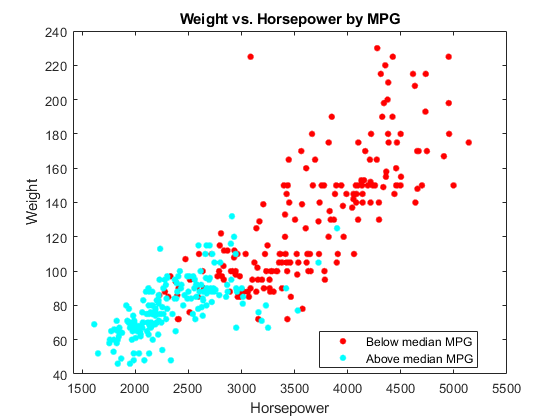

y = auto.mpg>=median(auto.mpg);
X = auto(:,2:8);
gscatter(auto.weight,auto.horsepower,y)
xlabel("Horsepower")
ylabel("Weight")
legend("Below median MPG", "Above median MPG")
title("Weight vs. Horsepower by MPG")

**(1c) **Split your data into a training and test set. For $n_{\textrm{train}} =300$, use the first $n_{\textrm{train}}$ entries of $y$ and rows of $X$ for training, and save the remaining entries/rows for testing the fitted model. 

ntrain = 300;
y_train = y(1:ntrain);
X_train = X(1:ntrain,:);
y_test = y(ntrain+1:end);
X_test = X(ntrain+1:end,:);

**(1d) **Call the built-in `MNRFIT` function on your training inputs and outputs to fit a classifier. Note that the second argument of `MNRFIT` must be a categorical variable. You can convert $y$ into a categorical variable using `categorical(y)`.

B = mnrfit(X_train{:,:},categorical(y_train));

**(1e) **Use the built-in function MNRVAL to evaluate your classifier on both the training and test sets. MNRVAL will return two values in each row; they are the probabilities that the car with the properties in that row has $y=0$ or $y=1$, respectively. You should set your prediction to be 0 if the first probability is higher than the second, and your prediction to be 1 otherwise. Hint: the syntax `(x>y)` where x and y are vectors of the same shape will return a third vector of the same shape with 1's where x>y and 0's otherwise.

probtrain = mnrval(B,X_train{:,:});
probtest = mnrval(B,X_test{:,:});
predtrain = probtrain(:,1)<=probtrain(:,2);
predtest = probtest(:,1)<=probtest(:,2);

**(1f) **Use `GSCATTER` to plot (i) the training data set horsepower & weight grouped according to whether the classifier prediction is correct or not, and (ii) the same for the test set. Hint: the syntax `x==y` for vectors x and y of the same shape returns a 1 when x = y and a 0 otherwise. Include appropriate axes labels, legends, and title.

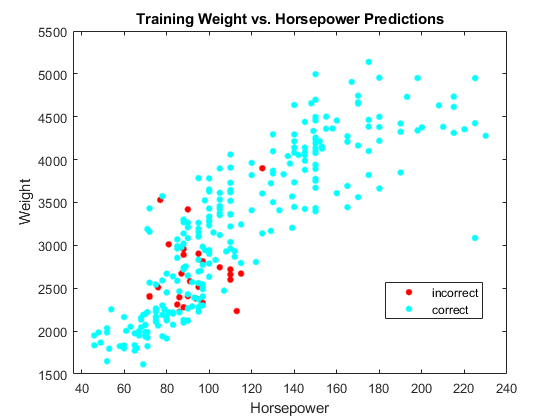

figure(1);clf;
gscatter(X_train.horsepower, X_train.weight, predtrain==y_train)
xlabel("Horsepower")
ylabel("Weight")
legend("incorrect", "correct")
title("Training Weight vs. Horsepower Predictions")

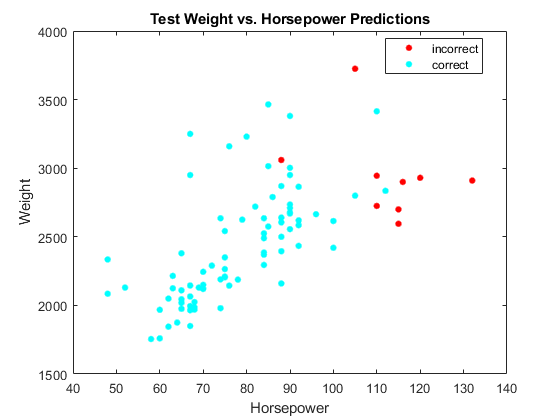


figure(2);clf;
gscatter(X_test.horsepower, X_test.weight, predtest==y_test)
xlabel("Horsepower")
ylabel("Weight")
legend("incorrect", "correct")
title("Test Weight vs. Horsepower Predictions")

**(1g) **What is the misclassification rate for the training set? For the test set? Misclassification rate = # of misclassified cars divided by total number of cars in the set.

training_rate = mean(predtrain~=y_train)

training_rate = 0.0967

test_rate = mean(predtest~=y_test)

test_rate = 0.0978

## **Problem 2: Classification via K-Nearest Neighbors**

Now, using the same training/test split as above, use the built-in funcion `FITCKNN` to fit a k-Nearest Neighbor (kNN) classifier. Specify the number of neighbors $k$ when fitting your kNN model, and try $k=1,\ldots, 50$. Train your model on the train set and test it your the test set using the `PREDICT` function. Compute the misclassification rate for both training and test sets. On the same axis, plot the misclassification rate for training and test sets vs $k$. 

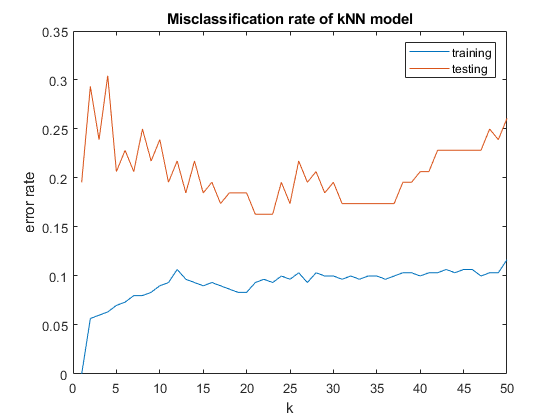

training_errrate = zeros(50,1);
test_errrate = zeros(50,1);

for k=1:50
    mdl = fitcknn(X_train,y_train,"NumNeighbors",k);
    label_train = predict(mdl,X_train);
    label_test = predict(mdl,X_test);
    training_errrate(k) = mean(label_train~=y_train);
    test_errrate(k) = mean(label_test~=y_test);
end

figure(3);clf;
plot(training_errrate)
hold on
plot(test_errrate)
hold off

xlabel("k")
ylabel("error rate")
legend("training", "testing")
title("Misclassification rate of kNN model")

Describe the general trends you observe in the training and test misclassification rates as the number of neighbors used to classify increases. For test error especially look for the overall large shape of the error function; there will be many small ups and downs that you should "smooth out" in your head. 

Training misclassification rates in general increase as the number of neighbors increase, with a sharp increase then flattening out. Test error in general decreases to around 20-25 neighbors then increases after.

How many neighbors leads to the lowest training error? The lowest test error? Explain why these are different.

The lowest training error is at 1 neighbors, but the lowest test error is 22-24 neighbors. These are different because the training error is garunteed to be 0 for 1 neighbor, but is overfit and will have higher error for the testing data.